cd('/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001')
ExperimentName='20220422_112_AChmtut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 23; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24 25]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24    25


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)
rawData=([Temperature_path,ExperimentName,'.mat'])

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001.mat'

OptResults=([Temperature_path,ExperimentName,'OptResults.mat'])

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults.mat'

load(rawData)

states = [states_pooled;states_pooled;states_pooled;states_pooled;states_pooled;states_pooled;states_pooled;states_pooled];
tau = [tau_empTrunc_pooled;tau_empTrunc_pooled;tau_empTrunc_pooled;tau_empTrunc_pooled;tau_empTrunc_pooled;tau_empTrunc_pooled;tau_empTrunc_pooled;tau_empTrunc_pooled];

rawData1 = ([Temperature_path,ExperimentName,'_1.mat'])

rawData1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001_1.mat'

OptResults1=([Temperature_path,ExperimentName,'OptResults_1.mat'])

OptResults1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults_1.mat'

save(rawData1, 'states','tau','time_pooled')

states_added = zeros(length(states_pooled), 1);
tau_added = nan(length(states_pooled), 1);

states = [states_added;states_pooled;states_added;states_pooled;states_added;states_pooled;states_added;states_pooled];
tau = [tau_added;tau_empTrunc_pooled;tau_added;tau_empTrunc_pooled;tau_added;tau_empTrunc_pooled;tau_added;tau_empTrunc_pooled];


rawData2 = ([Temperature_path,ExperimentName,'_2.mat'])

rawData2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001_2.mat'

OptResults2=([Temperature_path,ExperimentName,'OptResults_2.mat'])

OptResults2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults_2.mat'

save(rawData2, 'states','tau','time_pooled')

states_added = zeros(length(states_pooled), 1) + 1;
tau_added = zeros(length(states_pooled), 1) + mean(tau_empTrunc_pooled);

states = [states_added;states_pooled;states_added;states_pooled;states_added;states_pooled;states_added;states_pooled];
tau = [tau_added;tau_empTrunc_pooled;tau_added;tau_empTrunc_pooled;tau_added;tau_empTrunc_pooled;tau_added;tau_empTrunc_pooled];

rawData3 = ([Temperature_path,ExperimentName,'_3.mat'])

rawData3 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001_3.mat'

OptResults3=([Temperature_path,ExperimentName,'OptResults_3.mat'])

OptResults3 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults_3.mat'

save(rawData3, 'states','tau','time_pooled')

c=parcluster

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-mbp
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

j=batch(@example2_Optimization,1,{rawData1, OptResults1})

j = 

 Job

    Properties: 

                   ID: 44
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 16-Sep-2022 12:05:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

j=batch(@example2_Optimization,1,{rawData2, OptResults2})

j = 

 Job

    Properties: 

                   ID: 45
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 16-Sep-2022 12:06:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

j=batch(@example2_Optimization,0,{rawData3, OptResults3})

j = 

 Job

    Properties: 

                   ID: 46
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 16-Sep-2022 13:40:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

load(rawData2)
load(OptResults2)

flagsWakeREM = states_pooled_all;

initial_temperature = -1; % negative value produces an estimated initial temperature
SF=4;

% Use the median parameter values from Table 1:
p.sizePWP = 2;              % window size (in hours) of the prior wake prevelance (PWP)
p.shiftPWP = -1;          % window shift (in hours) of the prior wake prevelance (PWP)
p.lowerAsymptote = 4.2382;   % Lower asymptote value (in C)
p.upperAsymptote =  2.6096;  % Upper Asymptote value (in C)
p.wakeTimeConstant = 723.550;  % Time constant of wake and REM states
p.nremTimeConstant = 1.6165;  % Time constant of NREM sleep
p.scalePWP = 0.0377;          % The multiplier of PWP values
p.circadianAmplitude = 0.0738;% The multiplier of the circadian values
p.circadianPhase = 12.3417;   % Phase shift of circadian process (in hours)

[simulatedT,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

figure
plot(simulatedT)

load(rawData3)
load(OptResults3)

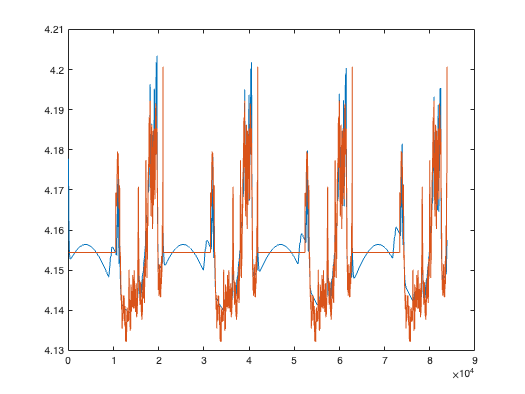

figure
plot(simulatedT)
hold on
plot(rawT)